%边缘检测 
I=imread('D:\matlab_project\image_process\WEEK6HW\lena.jpg');
%fil_I=mylvbo(I,'mean',2);
%fil_I=mylvbo(I,'fmedian',2);
%fil_I=mylvbo(I,'self_ad',[2 249]);
fil_I=mylvbo(I,'guass',[1 2]);

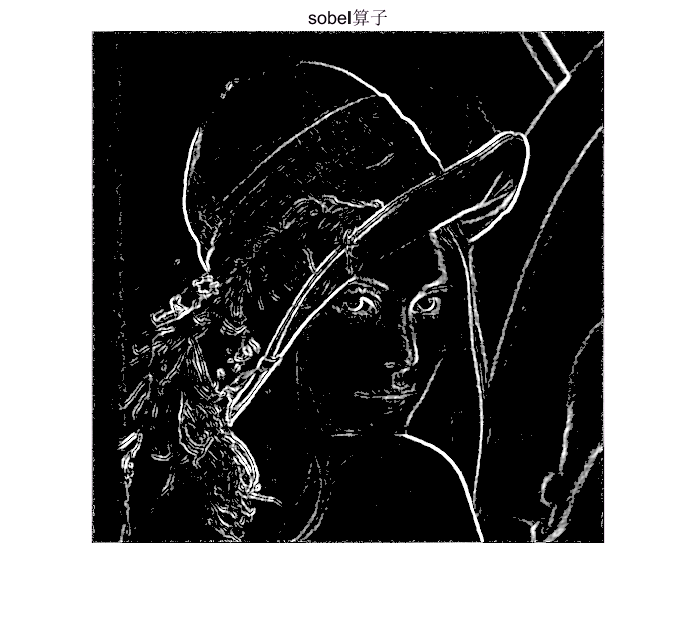

%sobel
edge_I=edge_detect(fil_I,'sobel',100,0);
imshow(edge_I);title('sobel算子');

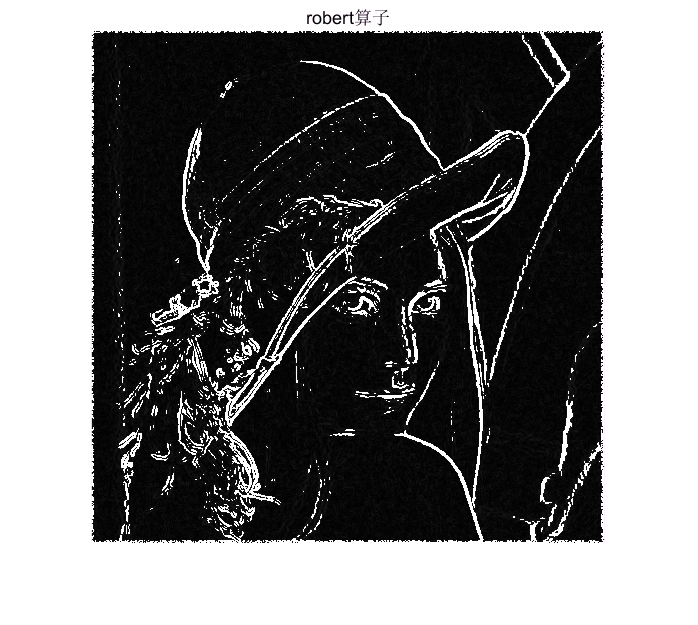

%robert
edge_I=edge_detect(fil_I,'robert',25,1);
imshow(edge_I);title('robert算子');

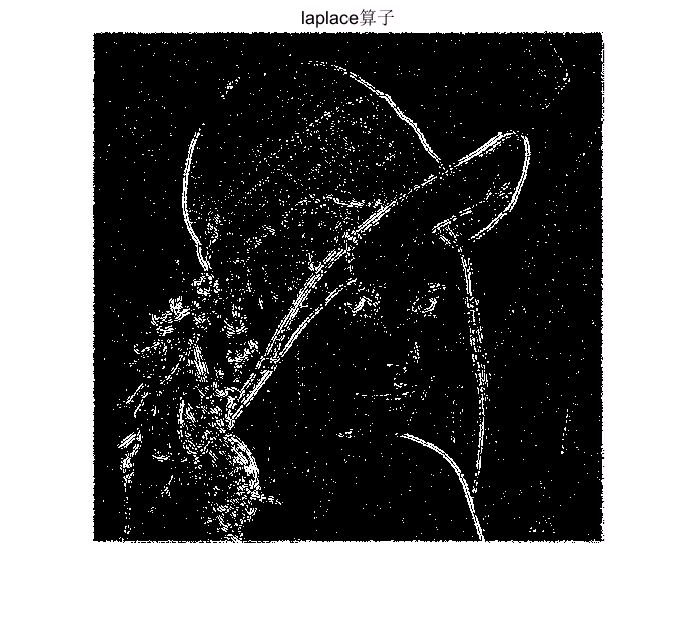

%laplace
edge_I=edge_detect(fil_I,'laplace',[40,2],0);
imshow(edge_I);title('laplace算子');

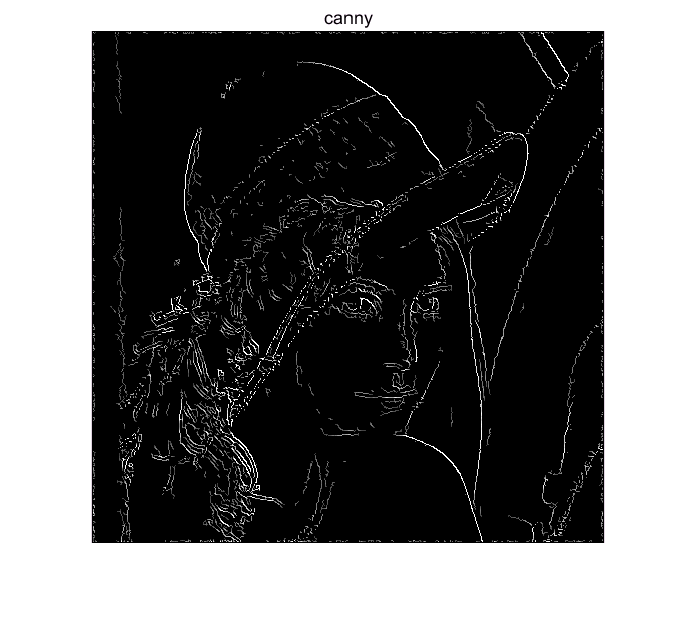

%canny
fil_I=mylvbo(I,'guass',[1.2 2]);
edge_I=edge_detect(fil_I,'canny',[60 110],0);
imshow(edge_I);title('canny');